usage: teamwork for week 12

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.5.24

clear all; close all; clc

**1. (1) 利用组合梯形公式计算积分**


$$    $$
    I=\int_0^1 \frac{\sin x}{x}dx
    $$$$


**    的近似值，使截断误差不超过**$$5\times 10^{-4}$$**.     **

**    (2) 对于相同的节点函数值， 若改用组合Simpson1/3公式计算结果如何？   **

**    提示：令**$$f(x)=\frac{\sin x}{x}$$**, 则**$$\vert f^{(k)}\vert\leq \frac{1}{k+1}$$**.**

解：

（1）由$$\vert f^{(k)}\vert\leq \frac{1}{k+1}$$，可知$$\vert f^{(2)}\vert\leq \frac{1}{2+1}=\frac13$$

clear all; close all; clc
f_1_max = 1/3;
f_1 = @(x) sin(x)./x;
b_1 = 1;
a_1 = 0 + 1e-10;
I_1_check = integral(f_1, a_1, b_1)

I_1_check = 0.9461

n_1 = 1;
while E_T(f_1_max, b_1, a_1, (b_1-a_1)/n_1) > 5e-4
    n_1 = n_1+1;
end
fprintf("满足截断误差的n为%d", n_1)

满足截断误差的n为8

I_1_TrapComp = TrapComp(f_1, a_1, b_1, n_1)

I_1_TrapComp = 0.9457

E_r_1_TrapComp = abs(I_1_TrapComp - I_1_check)/I_1_check;
fprintf("通过组合梯形公式计算的积分值与真实值相对误差为：%f%%", E_r_1_TrapComp*100)

通过组合梯形公式计算的积分值与真实值相对误差为：0.041456%

（2）

I_1_Simpson = Simpson(f_1, a_1, b_1, n_1)

I_1_Simpson = 0.9461

E_r_1_Simpson = abs(I_1_Simpson - I_1_check)/I_1_check;
fprintf("通过辛普森1/3公式计算的积分值与真实值相对误差为：%f%%", E_r_1_Simpson*100)

通过辛普森1/3公式计算的积分值与真实值相对误差为：0.000025%

可以看到对相同的节点划分，组合Simpson1/3公式计算的积分值与真实值的误差远小于组合梯形公式计算得到的与真实值之间的误差。

**2. (1) 编写程序应用辛普森1/3算法计算积分**


$$    $$
    I(x)=\int_0^x \frac{t^3}{e^t-1}dt
    $$     $$
       

**    (2) 请画出函数曲线**$$I(x)$$**.**

**    (3) 求当**$$x=?$$**时， **$$I(x)=5$$**.**

解：

（1）

clear all; close all; clc
f_2 = @(x) x.^3./(exp(x)-1);
I_2 = @(x) Simple_Simpson(f_2, 0, x);

I_2 = 包含以下值的 function_handle :
    @(x)Simple_Simpson(f_2,0,x)


（2）

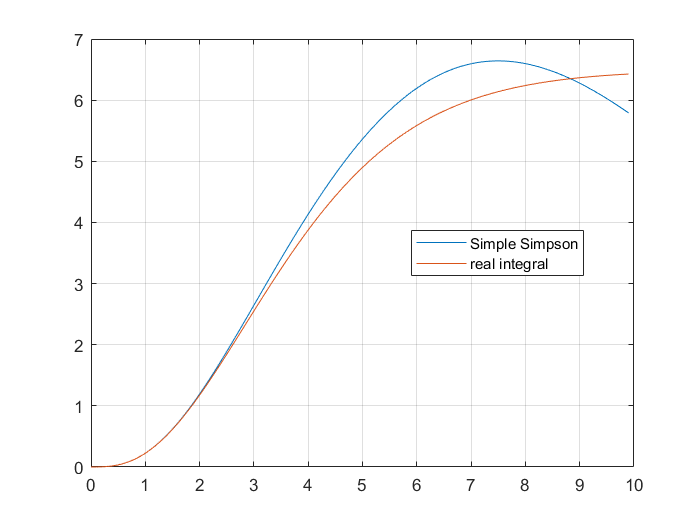

x_2 = 1e-8:0.1:10;
I_2_check = zeros(length(x_2), 1);
for i = 1:length(x_2)
    I_2_check(i) = integral(f_2, 0, x_2(i));
end
plot(x_2, I_2(x_2), x_2, I_2_check)
legend("Simple Simpson", "real integral", 'Location', 'best')
grid on

从图中可以看出，辛普森1/3算法计算的积分在x=8之后就开始减小，但原函数始终为正，积分理应始终增大，简单辛普森1/3公式计算的积分会出现严重误差。

（3）

% 用辛普森1/3算法求I(x)=5
x_2_3_Simple_Simpson = fzero(@(x) I_2(x) - 5, 1)

x_2_3_Simple_Simpson = 4.6713

% 用matlab的integral函数求I(x)=5
x_2_3_check = fzero(@(x) integral(f_2, 0, x) - 5, 1)

x_2_3_check = 5.1210

E_r_2_3 = abs(x_2_3_check - x_2_3_Simple_Simpson)/x_2_3_check;
fprintf("通过简单辛普森1/3公式求得的I(x)=5的解与真实值相差：%f%%", E_r_2_3*100)

通过简单辛普森1/3公式求得的I(x)=5的解与真实值相差：8.780980%

**3. 空气流过直径为16cm的圆形导管. 由导管的中心线开始， 在不同半径**$$r$$**处采集到如下的速度值：**

**    | **$$r_k$ $**  cm | 0    | 1.60 | 3.20 | 4.80 | 6.40 | 7.47 | 7.87 | 7.95 | 8    |**

**   | **$$v_k$ $** m/s | 10   | 9.69 | 9.30 | 8.77 | 7.95 | 6.79 | 5.57 | 4.89 | 0    |**

**   综合使用牛顿-科特斯面积公式计算质量流通率**$$S$$


$$   $$
   S=\int_0^R \rho v 2\pi r dr
   $$$$


**   其中**$$\rho$$**为密度(**$$\rho=1.2 kg/m^3$**). 请用kg/s表示你的结果。**

解：

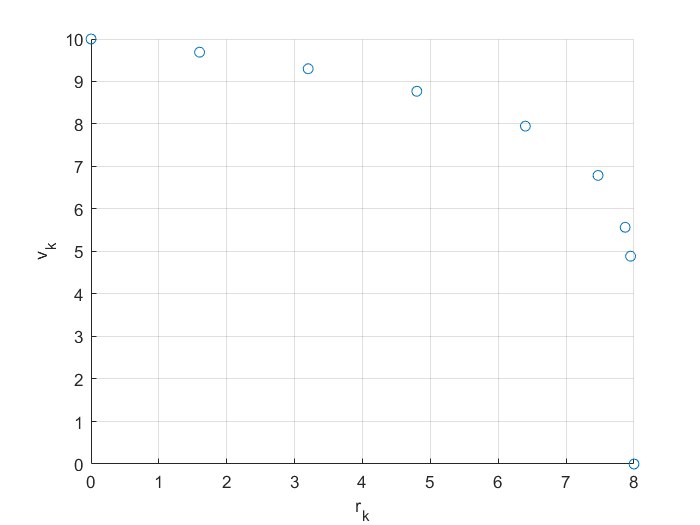

clear all; close all; clc
% 散点图观察数据
r_3 = [0, 1.6, 3.2, 4.8, 6.4, 7.47, 7.87, 7.95, 8];
v_3 = [10, 9.69, 9.3, 8.77, 7.95, 6.79, 5.57, 4.89, 0];
scatter(r_3, v_3)
xlabel("r_k")
ylabel("v_k")
grid on

% 被积的离散数据
dS_3 = 1.2.*v_3.*2.*pi.*r_3*1e-2;
% 当r从0-6.4都为1.6等间距的数据点，故采用组合辛普森1/3公式
S_3_1 = SimpsonDiscrete(0, 6.4, 4, dS_3(1:5));
% 当r从6.4-8数据点的间距不同，故采用组合梯形公式
S_3_2 = TrapCompDiscrete(r_3(5:end), dS_3(5:end));
S_3 = S_3_1 + S_3_2

S_3 = 19.5514

计算得到质量流通率$S\approx19.5514 kg/s$

**4. 使用隆贝格积分算法求**


$$   $$
   \int_0^{10}\ln \left(x+\sqrt{x^2+1}\right)
   $$$$


**   现在已知一阶隆贝格积分值， 求二阶和三阶隆贝格积分: **


$$   $$
   \pmatrix{
   19.0577 & ? &? \cr
   20.4281& ? & & \cr
   20.8107& &
 }
   $$$$


解：

根据公式$T_{jk}=\frac{4^{k-1}T_{j+1,k-1}-T_{j,k-1}}{4^{k-1}-1}$

clear all; close all; clc
T_4 = [1.2; 1.262; 1.281];
for k = 2:3
    for j = 1:4-k
        T_4(j,k) = (4^(k-1)*T_4(j+1, k-1) - T_4(j, k-1))/(4^(k-1) - 1);
    end
end
disp(T_4)

    1.2000    1.2827    1.2876
    1.2620    1.2873         0
    1.2810         0         0



**5. 求数值积分**


$$   $$
   I=\int_{0.8}^3\frac{1}{1+\sinh(2x)\ln(x)^2}
   $$$$


clear all; close all; clc
I_5 = integral(@(x) 1./(1+sinh(2.*x).*log(x).^2), 0.8, 3)

I_5 = 0.6768

% 利用组合辛普森公式进行求解
I_5_Simpson = Simpson(@(x) 1./(1+sinh(2.*x).*log(x).^2), 0.8, 3, 50)

I_5_Simpson = 0.6768

E_r_5_Simpson = abs(I_5_Simpson - I_5)/I_5;
fprintf("通过组合辛普森1/3公式计算的积分值与真实值相对误差为：%f%%", E_r_5_Simpson*100)

通过组合辛普森1/3公式计算的积分值与真实值相对误差为：0.000069%

**6. 计算积分**


$$   $$
   I=\int_0^\infty e^{-x^2}dx
   $$ $$


clear all; close all; clc
I_6 = integral(@(x) exp(-(x.^2)), 0, inf)

I_6 = 0.8862

I_6_check = sqrt(pi)/2

I_6_check = 0.8862

利用组合辛普森公式进行求解：

将积分分成0-1、1-+∞两端求，对后一段进行换元处理

n取较大的50以保证求解精度


$$I=\int_1^\infty e^{-x^2}dx = \int_0^1 \frac 1  {t^2}{e^{-\frac 1 {t^2}}}dx$$


f_6_1 = @(x) exp(-x.^2);
f_6_2 = @(x) exp(-1./(x.^2))./(x.^2);
I_6_1 = Simpson(f_6_1, 0, 1, 50);
I_6_2 = Simpson(f_6_2, 0+1e-10, 1, 50);
I_6_Simpson = I_6_1 + I_6_2

I_6_Simpson = 0.8862

E_r_6_Simpson = abs(I_6_Simpson - I_6)/I_6;
fprintf("通过组合辛普森1/3公式计算的积分值与真实值相对误差为：%f%%", E_r_6_Simpson*100)

通过组合辛普森1/3公式计算的积分值与真实值相对误差为：0.000001%

*******************************************function**************************************************

E_T：组合梯形公式的误差


$$|E_T|=\frac{(b-a)h^2}{12}max(|f^{(2)}(x)|)$$


function E = E_T(f, b, a, h)
    E = f.*(b-a).*h.^2./12;
end

TrapComp：组合梯形公式

function I = TrapComp(f,a,b,n)
%
% TrapComp estimates the value of the integral of f(x)
% from a to b by using the composite trapezoidal rule
% applied to n equal-length subintervals.
%
% I = TrapComp(f,a,b,n) where
%
% f is an inline function representing the integrand,
% a and b are the limits of integration,
% n is the number of equal-length subintervals in [a,b],
%
% I is the integral estimate.
%
% Ramin S. Esfandiari, Numerical Methods for Engineers and Scientists Using
% Matlab,
% Section 6.3.4, p.291
%
h = (b - a)/n;
x = a:h:b;
I = h * (f(a)/2. + sum(f(x(2:n))) + f(b)/2);
end

Simpson：组合辛普森1/3公式

function I = Simpson(f,a,b,n)
%
% Simpson estimates the value of the integral of f(x)
% from a to b by using the composite Simpson’s 1/3 rule
% applied to n equal-length subintervals.
%
% I = Simpson(f,a,b,n) where
%
% f is an inline function representing the integrand,
% a, b are the limits of integration,
% n is the (even) number of subintervals,
%
% I is the integral estimate.
%
% Ramin S. Esfandiari, Numerical Methods for Engineers and Scientists Using
% Matlab,
% Section 6.3.5, p.295
%
if mod(n,2) ~= 0
    error('n must be an even integer!')
end
h = (b - a)/n;
x = a:h:b;
I = h/3*(2*sum(f(x(1:2:end))) + ...
    4*sum(f(x(2:2:end))) - f(a) - f(b));
end

Simple_Simpson：简单辛普森1/3公式


$$\int^{x3}_{x1}f(x)dx\approx \frac h3(f_1+4f_2+f_3)$$


function I = Simple_Simpson(f, a, b)
    a = a + 1e-9;
    h = (b-a)./2;
    I = h/3.*(f(a) + 4*f((a+b)./2) + f(b));
end

SimpsonDiscrete：离散数据点的组合辛普森1/3公式

function I = SimpsonDiscrete(a,b,n,y)
%
% Simpson estimates the value of the integral of f(x)
% from a to b by using the composite Simpson’s 1/3 rule
% applied to n equal-length subintervals.
%
% I = Simpson(f,a,b,n) where
%
% f is an inline function representing the integrand,
% a, b are the limits of integration,
% n is the (even) number of subintervals,
%
% I is the integral estimate.
%
% Ramin S. Esfandiari, Numerical Methods for Engineers and Scientists Using
% Matlab,
% Section 6.3.5, p.295
%

if mod(n,2) ~= 0
    error('n must be an even integer!')
end
h = (b-a)/n;
I = h/3*(2*sum(y(1:2:end)) + ...
    4*sum(y(2:2:end)) - y(1) - y(end));
end

TrapCompDiscrete：离散数据点的组合梯形公式

function I = TrapCompDiscrete(x,y)
%
% I = TrapCompDiscrete(x,y) where
%
% I is the integral estimate.
%

I = 0;
for i = 1:length(x) - 1
   I = I + 0.5.*(x(i+1) - x(i))*(y(i) + y(i+1)); 
end
end